clear; clc; close all;
% 严格使用你提供的正确文件路径
data1 = load("D:\GitHub\Matlab\波形图\waves.mat");
data = data1.waves;
outputPath = 'D:\同步\毕业设计\毕业设计\毕业论文\Figure\Waves';
if ~exist(outputPath, 'dir'), mkdir(outputPath); end

x = data.x_BLB_X;
y = [data.x_I_SRAM_Q_Y data.x_I_SRAM_QB_Y data.x_BL_Y data.x_BLB_Y ...
     data.x_I_VSA_Q_Y data.x_I_VSA_QB_Y data.x_CLK_Y data.x_WL_Y ...
     data.x_WR_Y data.x_IN_Y data.x_R_Y];

time_markers = [5,10,15,20,25]*1e-9;
stage_labels = {'保持','写0','读0','写1','读1'};
stage_centers = [3.75,7.5,12.5,17.5,22.5]*1e-9;

% 调整figure高度以适应6个子图
figure('Position', [100, 100, 1000, 1400]);
set(gcf, 'renderer', 'painters');
set(gcf, 'color', 'w');

% 子图1: CLK（仅此图添加阶段文字标注）
subplot(6,1,1);
plot(x, y(:,7), 'k-', 'LineWidth', 2.5);
grid on;
ylabel('CLK (V)');
xlim([2.5e-9, 28e-9]);
ylim([-0.1, 0.8]);

% 添加灰色虚线
for i=1:length(time_markers)
    xline(time_markers(i), 'Color', [0.5 0.5 0.5], 'LineStyle', '--', ...
          'LineWidth', 1, 'Alpha', 0.5, 'HandleVisibility','off');
end

% 添加阶段文字标注（仅在最上方子图）
y_max = 1.1;
for i=1:length(stage_labels)
    text(stage_centers(i), y_max*1.08, stage_labels{i}, ...
         'HorizontalAlignment', 'center', 'FontSize', 10, ...
         'FontWeight', 'bold', 'HandleVisibility','off');
end

% 新增子图2: Q和QB（使用你指定的精确RGB颜色）
subplot(6,1,2);
plot(x, y(:,1), 'Color', [0.8500 0.3250 0.0980], 'LineStyle', '-', 'LineWidth', 2.5, 'DisplayName', 'Q');
hold on;
plot(x, y(:,2), 'Color', [0.3010 0.7450 0.9330], 'LineStyle', '-', 'LineWidth', 2.5, 'DisplayName', 'QB');
grid on;
ylabel('Q/QB (V)');
xlim([2.5e-9, 28e-9]);
ylim([-0.1, 0.8]);
legend('Location', 'best');

for i=1:length(time_markers)
    xline(time_markers(i), 'Color', [0.5 0.5 0.5], 'LineStyle', '--', ...
          'LineWidth', 1, 'Alpha', 0.5, 'HandleVisibility','off');
end

% 子图3: WL（原subplot(5,1,2)）
subplot(6,1,3);
plot(x, y(:,8), 'b-', 'LineWidth', 2.5);
grid on;
ylabel('WL (V)');
xlim([2.5e-9, 28e-9]);
ylim([-0.1, 0.8]);

for i=1:length(time_markers)
    xline(time_markers(i), 'Color', [0.5 0.5 0.5], 'LineStyle', '--', ...
          'LineWidth', 1, 'Alpha', 0.5, 'HandleVisibility','off');
end

% 子图4: WR（原subplot(5,1,3)）
subplot(6,1,4);
plot(x, y(:,9), 'r-', 'LineWidth', 2.5);
grid on;
ylabel('WR (V)');
xlim([2.5e-9, 28e-9]);
ylim([-0.1, 0.8]);

for i=1:length(time_markers)
    xline(time_markers(i), 'Color', [0.5 0.5 0.5], 'LineStyle', '--', ...
          'LineWidth', 1, 'Alpha', 0.5, 'HandleVisibility','off');
end

% 子图5: W_bit (IN)（原subplot(5,1,4)）
subplot(6,1,5);
plot(x, y(:,10), 'g-', 'LineWidth', 2.5);
grid on;
ylabel('W_bit (V)');
xlim([2.5e-9, 28e-9]);
ylim([-0.1, 0.8]);

for i=1:length(time_markers)
    xline(time_markers(i), 'Color', [0.5 0.5 0.5], 'LineStyle', '--', ...
          'LineWidth', 1, 'Alpha', 0.5, 'HandleVisibility','off');
end

% 子图6: R（原subplot(5,1,5)）
subplot(6,1,6);
plot(x, y(:,11), 'm-', 'LineWidth', 2.5);
grid on;
xlabel('Time (s)');
ylabel('R (V)');
xlim([2.5e-9, 28e-9]);
ylim([-0.1, 0.8]);

for i=1:length(time_markers)
    xline(time_markers(i), 'Color', [0.5 0.5 0.5], 'LineStyle', '--', ...
          'LineWidth', 1, 'Alpha', 0.5, 'HandleVisibility','off');

subplot(6,1,2)

end

% 导出tikz（更新了文件名以反映变化）
matlab2tikz(fullfile(outputPath, 'wave_control_with_q.tex'), ...
    'showInfo', false, ...
    'parseStrings', false, ...
    'strictFontSize', true, ...
    'relativePath', true, ...
    'extraAxisOptions', {'scaled ticks=false', 'clip=false'}, ...
    'figureOnly', true, ...
    'height', '\figureheight', ...
    'width', '\figurewidth');

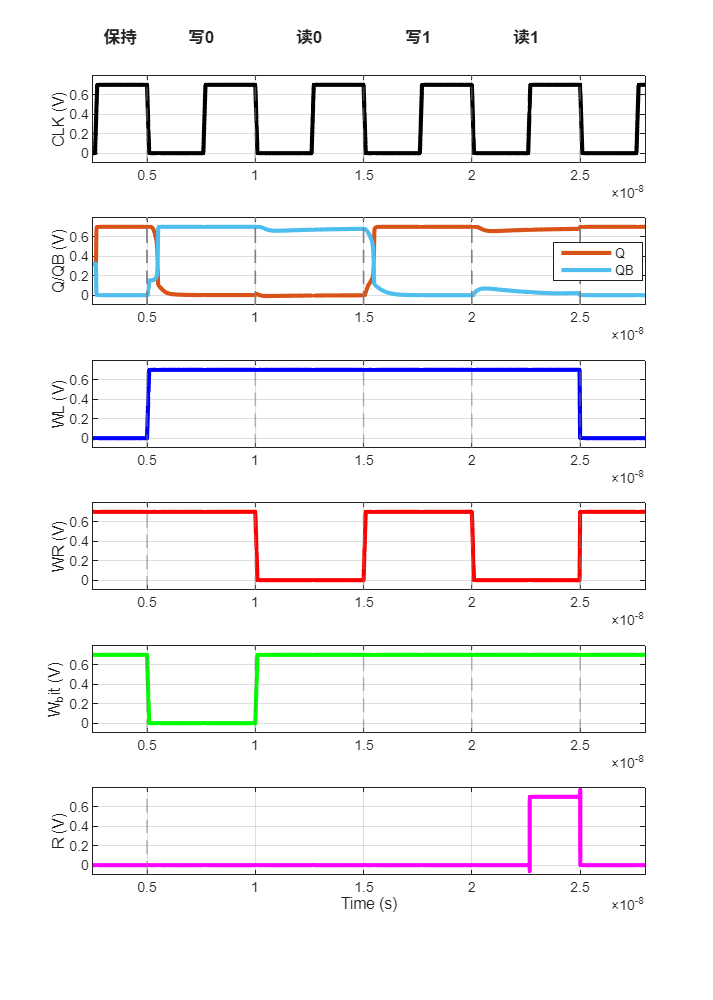

legend(["Q", "QB"], "Position", [0.7800 0.7208 0.1159, 0.0356])